# Optimal movement duration changes

The goal of this exercise is to determine how movement duration changes for different values of environment capture rate and metabolic cost of movement.

First we define the components of movement cost 

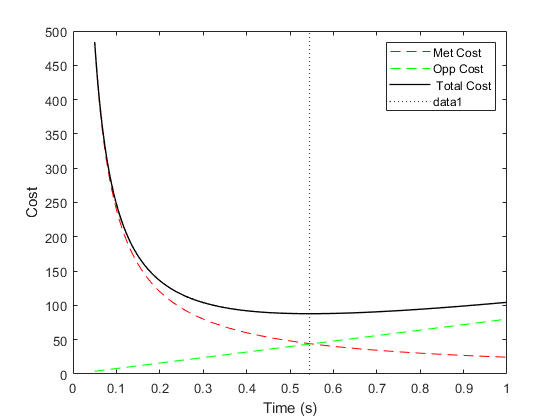

% First the effort cost of moving- slower is less effortful
um = @(t,a,b,m)(a*t + b*m./t);

% opportunity cost of the movement
om = @(t,rho)(rho*t);

t = 0.05:0.001:1;

% Plotting the different costs and the sum
% set dummy values to parameters
clf
b = 12;
a = 0.5;
rho = 80;
m=2;

plot(t, um(t,a,b,m), "r--");
hold on

plot(t, om(t,rho), ' g--')
hold on


tot_cost = @(t,a, b,m,rho) (um(t, a,b,m) + om(t,rho));
plot(t, tot_cost(t,a,b,m,rho), 'Color','k', 'LineWidth',1)
hold on
legend('Met Cost', 'Opp Cost',' Total Cost')

[~, opt_dur_ix] = min(tot_cost(t,a,b,m,rho));
xline(t(opt_dur_ix),'k:','Linewidth',1);
xlabel('Time (s)')
ylabel('Cost')


beautifyfig

'beautifyfig' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\shrut\Documents\Research\foraging_reward\mfiles
    C:\Users\shrut\Documents\Research\foraging_project\mfiles
    C:\Users\shrut\Documents\Research\overcoming_temptations

Change the MATLAB current folder or add its folder to the MATLAB path.

hold off


So now what happens when you change the mass within the same environment. ($\rho$ remains the same) 

m1 = 1;
m2 = 3;

tot_cost11 = tot_cost(t,a,b,m1,rho);
tot_cost23 = tot_cost(t,a,b,m2,rho);

[~,opt_dur_ix1] = min(tot_cost11);
[~,opt_dur_ix2] = min(tot_cost23);

plot(t, tot_cost11,'b--', t, tot_cost23, 'r--');
hold on

xline(t(opt_dur_ix1),'b:','Linewidth',1.5);
hold on

xline(t(opt_dur_ix2),'r:','Linewidth',1.5);
hold off

xlabel('Time (s)')
ylabel('Cost')

legend('m=1kg', 'm=3kg','Opt Dur 1kg','Opt Dur 3kg')

beautifyfig

dur11 = t(opt_dur_ix1);
dur12 = t(opt_dur_ix2);

Now in a separate environment let us look at the differences in  movement duration between two other masses. (We are going to ignore the fact that mass changes itself change the environment for now)

m3 = 4.5;
rho2 = 60;

tot_cost22 = tot_cost(t,a,b,m2,rho2);
tot_cost23 = tot_cost(t,a,b,m3,rho2);

[~,opt_dur_ix1] = min(tot_cost22);
[~,opt_dur_ix2] = min(tot_cost23);

plot(t, tot_cost22,'b--', t, tot_cost23, 'r--');
hold on
xline(t(opt_dur_ix1),'b:','Linewidth',1.5);
hold on

xline(t(opt_dur_ix2),'r:','Linewidth',1.5);
hold off

xlabel('Time (s)')
ylabel('Cost')

legend('m=3kg', 'm=4.5kg','Opt Dur 3kg','Opt Dur 4.5kg')

beautifyfig

dur22 = t(opt_dur_ix1);
dur23 = t(opt_dur_ix2);


Now let us look at what the differences look like in a single plot. 

%
plot([1,3],1./[dur11, dur12],'b-', 'LineWidth',1.5);
hold on
plot([3,4.5],1./[dur22, dur23],'r-', 'LineWidth',1.5);
ylim([0,6])
xlim([0,5])

xlabel('Mass (kg)');
ylabel('Velocity (1/tm) ');
legend('Low Effort','High Effort')

beautifyfig
hold off


% Changing b - increasing it to see if sensitivity to mass decreases
m1 = 1;
m2 = 3;

a=.5;
b= 2;
rho= 80;
tot_cost11 = tot_cost(t,a,b,m1,rho);
tot_cost23 = tot_cost(t,a,b,m2,rho);

[~,opt_dur_ix1] = min(tot_cost11);
[~,opt_dur_ix2] = min(tot_cost23);
dur11 = t(opt_dur_ix1);
dur12 = t(opt_dur_ix2);
rho2 = 60;

tot_cost22 = tot_cost(t,a,b,m2,rho2);
tot_cost23 = tot_cost(t,a,b,m3,rho2);

[~,opt_dur_ix1] = min(tot_cost22);
[~,opt_dur_ix2] = min(tot_cost23);
dur22 = t(opt_dur_ix1);
dur23 = t(opt_dur_ix2);


Now let us look at what the differences look like in a single plot. 

%
plot([1,3],1./[dur11, dur12],'b-', 'LineWidth',1.5);
hold on
plot([3,4.5],1./[dur22, dur23],'r-', 'LineWidth',1.5);
% ylim([0,3])
xlim([0,5])
xlabel('Mass (kg)');
ylabel('Velocity (1/tm) ');
legend('Low Effort','High Effort')

beautifyfig
hold off

Looking at the effect of different environment capture rates on the same movement mass


rho2 = 60;

tot_cost22 = tot_cost(t,a,b,m2,rho2);
rho3 = 80;
tot_cost32 = tot_cost(t,a,b,m2,rho3);

[~,opt_dur_ix1] = min(tot_cost22);
[~,opt_dur_ix2] = min(tot_cost32);

plot(t, tot_cost22,'b--', t, tot_cost32, 'r--');
hold on
xline(t(opt_dur_ix1),'b:','Linewidth',1.5);
hold on

xline(t(opt_dur_ix2),'r:','Linewidth',1.5);
hold off

xlabel('Time (s)')
ylabel('Cost')

legend('\rho = 60', '\rho = 80','Opt Dur 60','Opt Dur 80')

beautifyfig

Making the high effort environment have higher capture rate; this gives us the flipped results we're talking about. 


m1 = 1;
m2 = 3;
m3 = 4.5;

rho1= 60;
rho2 = 100;

tot_cost11 = tot_cost(t,a,b,m1,rho);
tot_cost23 = tot_cost(t,a,b,m2,rho);

[~,opt_dur_ix1] = min(tot_cost11);
[~,opt_dur_ix2] = min(tot_cost23);
dur11 = t(opt_dur_ix1);
dur12 = t(opt_dur_ix2);


tot_cost22 = tot_cost(t,a,b,m2,rho2);
tot_cost23 = tot_cost(t,a,b,m3,rho2);

[~,opt_dur_ix1] = min(tot_cost22);
[~,opt_dur_ix2] = min(tot_cost23);
dur22 = t(opt_dur_ix1);
dur23 = t(opt_dur_ix2);

%
plot([1,3],1./[dur11, dur12],'b-', 'LineWidth',1.5);
hold on
plot([3,4.5],1./[dur22, dur23],'r-', 'LineWidth',1.5);
% ylim([0,3])
xlim([0,5])
xlabel('Mass (kg)');
ylabel('Velocity (1/tm) ');

legend('Low Effort','High Effort')

beautifyfig
hold off

### From these results it appears that the changes in peak velocity differences between the two environments arise from an increase in capture rate in the high effort environment. So why would this happen? Would this be a consequence of finite integration? 

Why is the high effort environment also the one with higher capture rate? Based on Clement et al's (2000) work, we can test the state-dependence of subjective value theory. 

Let us try to build the average reward rate from scratch.

rho_init = 0;
clf

% reward function
alpha =  300;
beta = 0.5;
Fg = 8; % Force level required
u_h = @(alpha, beta, th) alpha*(1 - 1./(1+ beta*th)) - Fg*th;
ru_h = @(alpha,beta, th) (alpha*beta./ (1+ beta*th).^2) - Fg;


th = 0.:0.01:15;
plot(th, u_h(alpha,beta, th),'r--')
xlabel('Time (s)')
hold on

plot(th, ru_h(alpha, beta, th), 'k--')



### Simulating what a subject goes through within a patch 

% first harvest duration
clf;
tmax = 10*60;
th = 0:0.001:15;

clrs = {'b*','r*'};
m_prb = 3;
env = 1;
for m_env = [1, 4.5]
    
    rho = rho_init; % assuming it  is reset (no order effect);
    rho_nr = 0;
    tcurr = 0;
    hm = 0; % starting with harvest
    
    tr = 1;
    while tcurr < tmax
        
        % determine the mass at the arm
        tr_mod = mod(tr,50);
        if tr_mod >=21 && tr_mod <=30
            m1=m_prb;
        else
            m1=m_env;
        end
        
        if hm == 0
            ix_h = find(ru_h(th)<= rho,1,'first');
            t_h = th(ix_h);
            uh_itr = u_h(t_h);
            add_ = uh_itr;
            add_t = t_h;
            if isempty(t_h)
                keyboard
            end
            hm= 1;
        else
            [um_itr,ix_m] = min(tot_cost(t,a,b,m1,rho));
            t_m = th(ix_m);
            add_ = -1*um_itr;
            add_t = t_m;
            hm=0;
        end
        
        rho_nr = rho_nr + add_;
        tcurr = tcurr + add_t;
        rho = rho_nr/tcurr;
        subplot(131)
        plot(tcurr, rho, clrs{env});
        drawnow
        hold on;
        ylabel('Average Capture Rate')
        
        if hm==1
            subplot(132)
            ylabel('Harvest Duration')
        else
            subplot(133);
            ylabel('Movement Duration')
        end
        plot(tcurr,add_t,clrs{env});
        drawnow
        hold on
        
        
        tr = tr+1;
    end
    env = env+1;
end

The above simulation shows the predictions of MVT with added updating of average reward rate. Now we can add the increased value to the reward rate based on within trial contrasts. 

% first harvest duration
clf;
tmax = 10*60;
th = 0:0.001:15;
rho_init = 0;

clrs = {'b*','r*'};
m_prb = 3;
env = 1;

w_effort = 0.2; % positive effort weighting

for m_env = [1, 4.5]
    
    rho = rho_init; % assuming it  is reset (no order effect);
    rho_nr = 0;
    tcurr = 0;
    um_itr = 0;
    hm = 0; % starting with harvest
    
    tr = 1;
    while tcurr < tmax
        
        % determine the mass at the arm
        tr_mod = mod(tr,50);
        if tr_mod >=21 && tr_mod <=30
            m1=m_prb;
        else
            m1=m_env;
        end
        
        if hm == 0
            
            ix_h = find(ru_h(alpha, beta, th)<= rho,1,'first');
            t_h = th(ix_h);
            uh_itr = u_h(alpha,beta,t_h);
            add_ = uh_itr ;
            add_ = (50000/(50000 + rho_nr))*add_+ w_effort*um_prev;
            add_t = t_h;
            
            if isempty(t_h)
                keyboard
            end
            hm= 1;
            
        else
            
            [um_itr,ix_m] = min(tot_cost(t,a,b,m1,rho));
            t_m = th(ix_m);
            add_ = 0; %-1*um_itr;
            add_t = t_m;
            hm=0;
            
        end
        
        rho_nr = rho_nr + add_;
        tcurr = tcurr + add_t;
        rho = rho_nr/tcurr;
        
        subplot(131)
        plot(tcurr, rho, clrs{env});
        drawnow
        hold on;
        ylabel('Average Capture Rate')
        
        if hm==1
            subplot(132)
            ylabel('Harvest Duration')
        else
            subplot(133);
            ylabel('Movement Duration')
        end
        plot(tcurr,add_t,clrs{env});
        drawnow
        hold on
        
        um_prev = um_itr;
        
        tr = tr+1;
    end
    env = env+1;
end


## Reward Sensitivity

The hypothesis here is that incurring costs (such as effort costs) is an attempt to reduce the current reward state so as to increase the reward sensitivity. 

First, let us look at the sensitivity function - here I assume this to be a sigmoid: particularly a tanh function

%
clf
logi = @(beta_,x) ( 1./(1+exp(-1 *beta_*x)) );
tanh_ = @(beta_,L,x) (2*L*logi(beta_, 2*x) - L);

betas = 0.005;
x = -500:.1:500;

for beta_ = betas
    
    plot(x, tanh_(beta_, 300, x));
    drawnow
    hold on
    
end

Let us now use the reward sensitivity functionto determine how much the reward should be

k = 0.005;

% first harvest duration
clf;
tmax = 10*60;
th = 0:0.001:15;
rho_init = 0;

clrs = {'b*','r*'};
m_prb = 3;
env = 1;

tm_w = 0.9;

w_effort = 0.1; % positive effort weighting

for m_env = [1, 4.5]
    
    rho = rho_init; % assuming it  is reset (no order effect);
    rho_nr = 0;
    tcurr = 0;
    um_itr = 0;
    hm = 0; % starting with harvest
    
    tr = 1;
    while tcurr < tmax
        
        % determine the mass at the arm
        tr_mod = mod(tr,50);
        if tr_mod >=21 && tr_mod <=30
            m1=m_prb;
        else
            m1=m_env;
        end
        
        if hm == 0
            
            ix_h = find(ru_h(th)<= rho,1,'first');
            t_h = th(ix_h);
            uh_itr = u_h(t_h);
            %             add_ = tanh_(k,300,rho_nr+uh_itr) - tanh_(k,300,rho_nr);
            add_ = uh_itr;
            add_ = (50000/(50000 + rho_nr))*add_;
            add_t = 0.01*randn(1,1) + t_h;
            
            if isempty(t_h)
                keyboard
            end
            hm= 1;
            
        else
            
            [um_itr,ix_m] = min(tot_cost(th,a,b,m1,rho));
            t_m = th(ix_m);
            add_ = -1*um_itr;
            add_t = 0.001*randn(1,1) + t_m;
            hm=0;
            
        end
        
        rho_nr = rho_nr + add_;
        tcurr = tcurr + add_t;
        rho = rho_nr/tcurr;
        
        subplot(131)
        plot(tcurr, rho, clrs{env});
        drawnow
        hold on;
        ylabel('Average Capture Rate')
        
        
        if hm==1
            subplot(132)
            ylabel('Harvest Duration (s)')
        else
            subplot(133);
            ylabel('Movement Duration (s)')
        end
        plot(tcurr,add_t,clrs{env});
        drawnow
        hold on
        
        um_prev = um_itr;
        
        tr = tr+1;
    end
    env = env+1;
end

with just two alpha 

k = 0.005;

% first harvest duration
clf;
tmax = 10*60;
th = 0:0.001:15;
rho_init = 0;

clrs = {'b*','r*'};
m_prb = 3;
env = 1;
alpha1= 300;
alpha2 = 500;
alpha_prb = 400;
tm_w = 0.9;

w_effort = 0.1; % positive effort weighting

for m_env = [alpha1, alpha2]
    
    rho = rho_init; % assuming it  is reset (no order effect);
    rho_nr = 0;
    tcurr = 0;
    um_itr = 0;
    hm = 0; % starting with harvest
    
    tr = 1;
    while tcurr < tmax
        
        % determine the mass at the arm
        tr_mod = mod(tr,50);
        
        m1 = m_prb;
        
        if tr >=21 && tr<=30
            alpha = alpha_prb;
        end
        
        if hm == 0
            
            ix_h = find(ru_h(alpha, beta, th)<= rho,1,'first');
            t_h = th(ix_h);
            uh_itr = u_h(alpha, beta, t_h);
            add_ = uh_itr;
            add_t = 0.01*randn(1,1) + t_h;
            
            if isempty(t_h)
                keyboard
            end
            hm= 1;
            
        else
            
            [um_itr,ix_m] = min(tot_cost(th,a,b,m1,rho));
            t_m = th(ix_m);
            add_ = -1*um_itr;
            add_t = 0.001*randn(1,1) + t_m;
            hm=0;
            
        end
        
        rho_nr = rho_nr + add_;
        tcurr = tcurr + add_t;
        rho = rho_nr/tcurr;
        
        subplot(131)
        plot(tcurr, rho, clrs{env});
        drawnow
        hold on;
        ylabel('Average Capture Rate')
        
        
        if hm==1
            subplot(132)
            ylabel('Harvest Duration (s)')
        else
            subplot(133);
            ylabel('Movement Duration (s)')
        end
        plot(tcurr,add_t,clrs{env});
        drawnow
        hold on
        
        um_prev = um_itr;
        
        tr = tr+1;
    end
    env = env+1;
end

Simulating Gary and Dan's probability of reward experiment - the 4  target experiment. For a certain block size N each target is sampled N/4 times without replacement. Targets number 1-4 have a probability of reward [0,0.3,0.6,1]. 

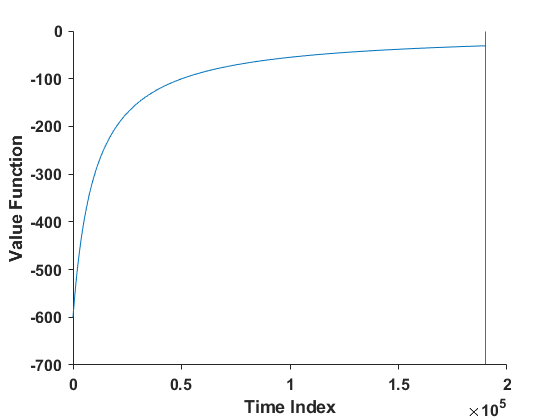

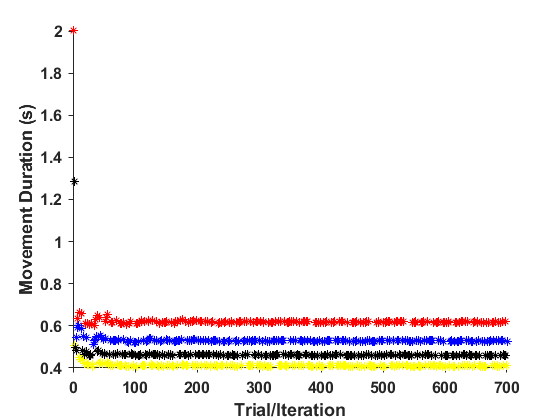

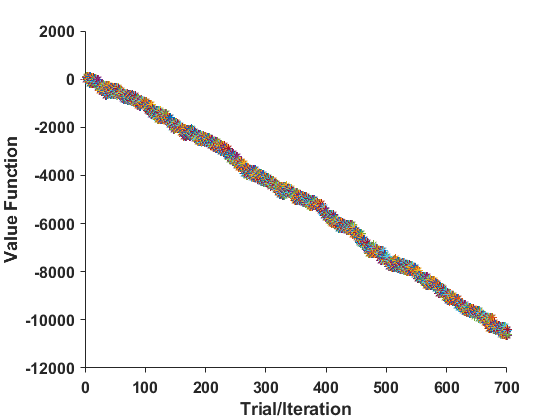

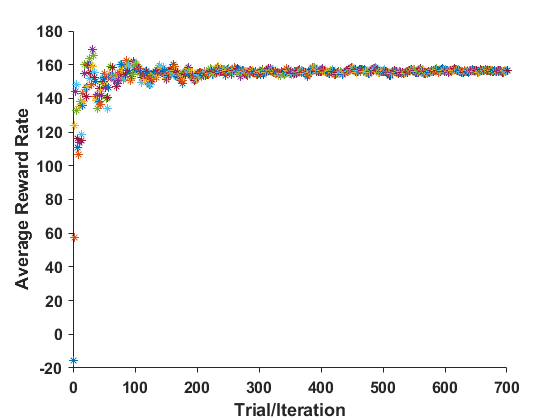

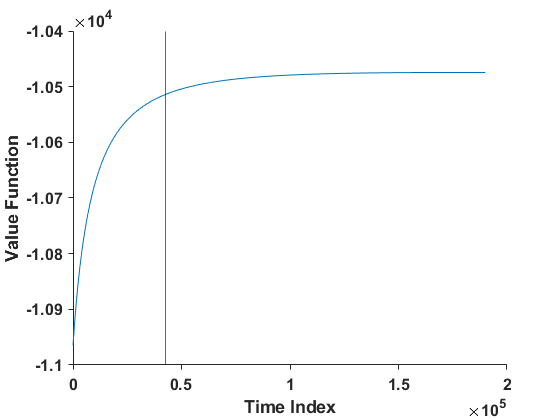

%
clf;
tmax = 10*60;
th = 0.1:0.00001:2; % discretized time for ghetto time optimization
rho_init = 0;
m1 = 5;
alpha= 400; % standard value
w_effort = 0.1; % positive effort weighting
a=0.5;
rho = rho_init; % assuming it  is reset (no order effect);
rho_nr = 0;
um_itr = 0;

max_tr = 700;
N=3;
targs = 1:4;
sampl_arr = [];
probs = [0, 0.34, 0.67, 1];
Val = [0 0 0 0] + 0.01*randn(1);
tcurr =0;


clrs={'r*','b*','k*','y*'};

data_sim = struct('targs',[],'t_mov',[]);
for tr = 1:max_tr
    
    if isempty(sampl_arr)
        for i = 1:N
            sampl_arr = [sampl_arr, targs];
        end
        sampl_arr = sampl_arr(randperm(N*4));
        num_tar = ones(1,4)*N;
    end
    targ_ix = sampl_arr(1);
    num_tar(targ_ix) = num_tar(targ_ix)-1;
    
    if length(sampl_arr) > 1
        sampl_arr = sampl_arr(2:end);
        prob_transition = num_tar/length(sampl_arr);
    else
        sampl_arr = [];
        prob_transition = ones(1,4)/4;
    end
    
    
    % determine the mass at the arm

    rwd_tar = probs(targ_ix)*alpha;
    c_m = um(th,a,b,m1);
    add_ = rwd_tar./(1+th) - c_m;
    
    %     subplot(221)
    figure(1)
    plot(add_ + sum(prob_transition.*Val))
    hold on
    
    [Val(targ_ix),tm_ix] = max(add_ - rho*th + sum(prob_transition.*Val)); % For now assuming the transition probability is 0.25
    xline(tm_ix);
    xlabel('Time Index')
    ylabel('Value Function')
    beautifyfig
    hold off
    drawnow
    t_m = th(tm_ix);
    %     Val(targ_ix) = Val(targ_ix) - rho*t_m;
    
    add_t = t_m;
    
    %     keyboard
    rho_nr = rho_nr + rwd_tar - c_m(tm_ix);
    tcurr = tcurr + add_t;
    rho = rho_nr/tcurr;
    
    um_prev = um_itr;
    
    %     subplot(2,2,targ_ix)
    %     subplot(222)
    figure(2)
    plot(tr,t_m,clrs{targ_ix})
    xlabel('Trial/Iteration')
    ylabel('Movement Duration (s)')
    beautifyfig
    hold on
    drawnow
    %     subplot(223);
    figure(3)
    plot(tr,Val,'*')
    xlabel('Trial/Iteration')
    ylabel('Value Function')
    beautifyfig
    drawnow
    hold on
    
    %     subplot(224);
    figure(4)
    plot(tr,rho,'*')
    xlabel('Trial/Iteration')
    ylabel('Average Reward Rate')
    beautifyfig
    drawnow
    hold on
    
    data_sim.targs(end+1) = targ_ix;
    data_sim.t_mov(end+1) = t_m;
end

Now determining how the movement vigor with target

%
rearr_tm = cell(1,4);
for t = targs
    rearr_tm{t} = data_sim.t_mov(data_sim.targs==t);
    
end

